**Question 3:**

Loading the data to get a better understanding of the feature formats and labels, and using the whole dataset for training:

myStruct = load('dataset4.mat');
x = myStruct.X

x =     0.4989   -0.3660    1.0000
    0.6831    0.1958    1.0000
    0.6760   -0.7508    1.0000
    0.9323    0.7761    1.0000
    0.8030   -0.9557    1.0000
    0.6607    0.1904    1.0000
    0.6408   -0.6335    1.0000
    0.1746    0.3278    1.0000
    0.2525    0.1604    1.0000
    0.5530    0.1009    1.0000


y = myStruct.Y

y =      0
     1
     0
     1
     0
     1
     0
     0
     0
     1


Next, I define the following parameters to later use it in the function for training the model:

tolerance = 0.001;
step_size = 0.1;
max_iterations = 300000;

Calling the function described below, and seeing the results of the binary classification error and the empirical risk:

[risk, model] = logisticreg(x, y, tolerance, step_size, max_iterations);

Iteration 1: Empirical Risk = 0.693147
Iteration 2: Empirical Risk = 0.688847
Iteration 3: Empirical Risk = 0.684628
Iteration 4: Empirical Risk = 0.680487
Iteration 5: Empirical Risk = 0.676425
Iteration 6: Empirical Risk = 0.672438
Iteration 7: Empirical Risk = 0.668526
Iteration 8: Empirical Risk = 0.664687
Iteration 9: Empirical Risk = 0.660920
Iteration 10: Empirical Risk = 0.657222
Iteration 11: Empirical Risk = 0.653593
Iteration 12: Empirical Risk = 0.650031
Iteration 13: Empirical Risk = 0.646536
Iteration 14: Empirical Risk = 0.643104
Iteration 15: Empirical Risk = 0.639735
Iteration 16: Empirical Risk = 0.636429
Iteration 17: Empirical Risk = 0.633182
Iteration 18: Empirical Risk = 0.629995
Iteration 19: Empirical Risk = 0.626865
Iteration 20: Empirical Risk = 0.623792
Iteration 21: Empirical Risk = 0.620775
Iteration 22: Empirical Risk = 0.617812
Iteration 23: Empirical Risk = 0.614901
Iteration 24: Empirical Risk = 0.612043
Iteration 25: Empirical Risk = 0.609236
Iteration

Visualizing the 2D data in the plot:

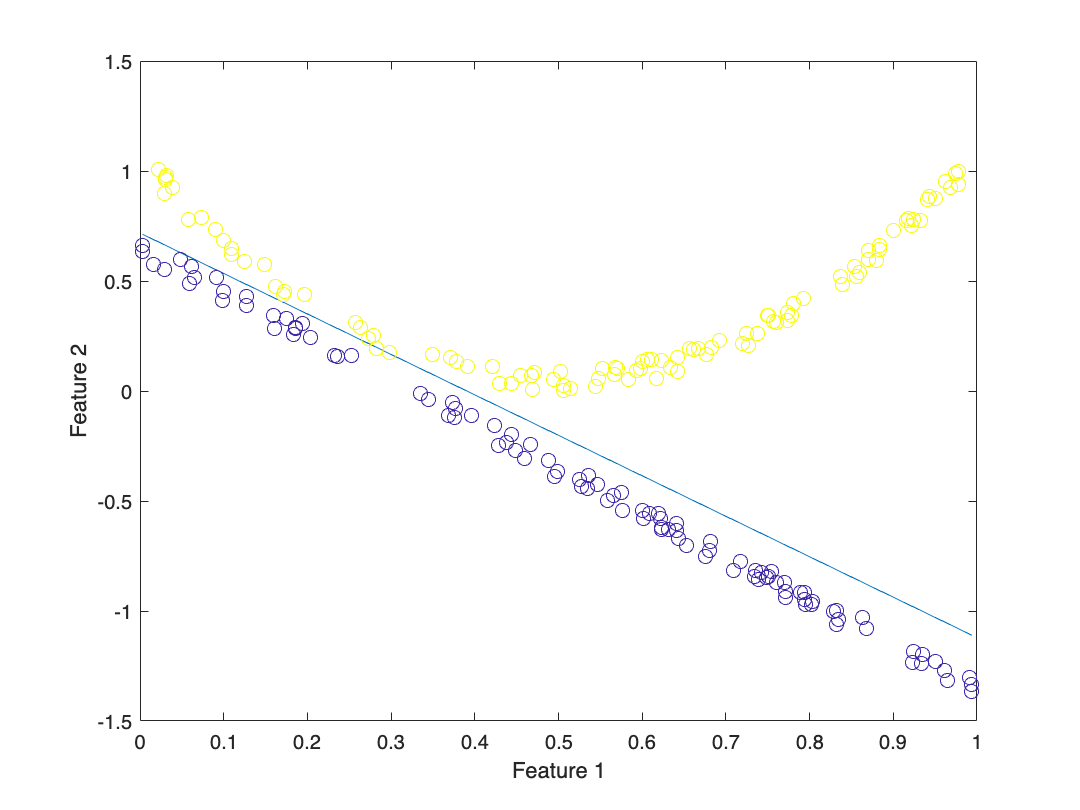

visualize(x, y, model);

The main function for training the logistic regression model, the sigmoid function, and the function for visually analyzing the decision boundary:

For the visualization function, the 3D data needs to be projected to 2D.

function [risk, model] = logisticreg(x, y, tolerance, step_size, max_iterations)

    model = zeros(size(x, 2), 1);

    for iter = 1:max_iterations

        z = x * model;
        predictions = sigmoid(z);
        gradient = (-1/length(x)) * (x' * (y - predictions));
        model = model - (step_size * gradient);
        risk = (1 / length(x)) * sum(((y - 1) .* log(1 - predictions)) - (y .* log(predictions)));

        fprintf('Iteration %d: Empirical Risk = %f\n', iter, risk);

        if abs(risk) < tolerance
            fprintf('Converged.\n');
            break; 
        end

    end
end


function s = sigmoid(z)
    s = 1 ./ (1 + exp(-z));
end


function visualize(x, y, model)
    plot(x(:, 1), -(x(:, 1)*model(1,:) + model(3,:))/model(2,:) )
    hold on;
    scatter(x(:, 1), x(:, 2), 50, y);
    xlabel('Feature 1');
    ylabel('Feature 2');
    hold off;

end